# Spar Mass Model

All models are of the form:


$$mass_{spar} = c \cdot (mass_{supported}\cdot FOS)^m \cdot (span)^n$$


where:

$mass_{spar}$ is the spar mass,

$mass_{supported}$ is the total mass of the fuselages + tails,

$FOS$ is the structural factor of safety, measured relative to a static load case,

$span$ is the wingspan,

and $c$, $m$, and $n$ are constants, given below for three configuration cases.

Single Boom:

clear
load data_single_boom.mat
fit = createFit(Masses,Spans,Spar_Masses*2);
title("Single Boom")
names = coeffnames(fit);
vals = coeffvalues(fit);
for i=1:length(names)
    disp(sprintf("%s = %.16f", names{i}, vals(i)))
end

c = 0.0082116578817492
m = 0.3380385531034899
n = 1.6500210118367851


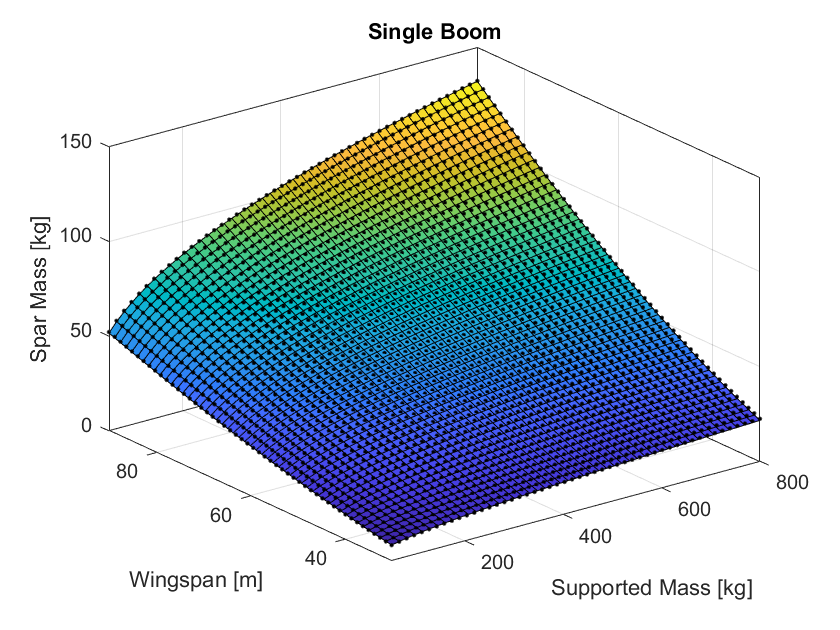

saveas(gcf,"plot_single_boom.png")

Double Boom:

clear
load data_double_boom.mat
fit = createFit(Masses,Spans,Spar_Masses*2);
title("Double Boom")
names = coeffnames(fit);
vals = coeffvalues(fit);
for i=1:length(names)
    disp(sprintf("%s = %.16f", names{i}, vals(i)))
end

c = 0.0038966832809997
m = 0.3472862388655697
n = 1.6222231509034950


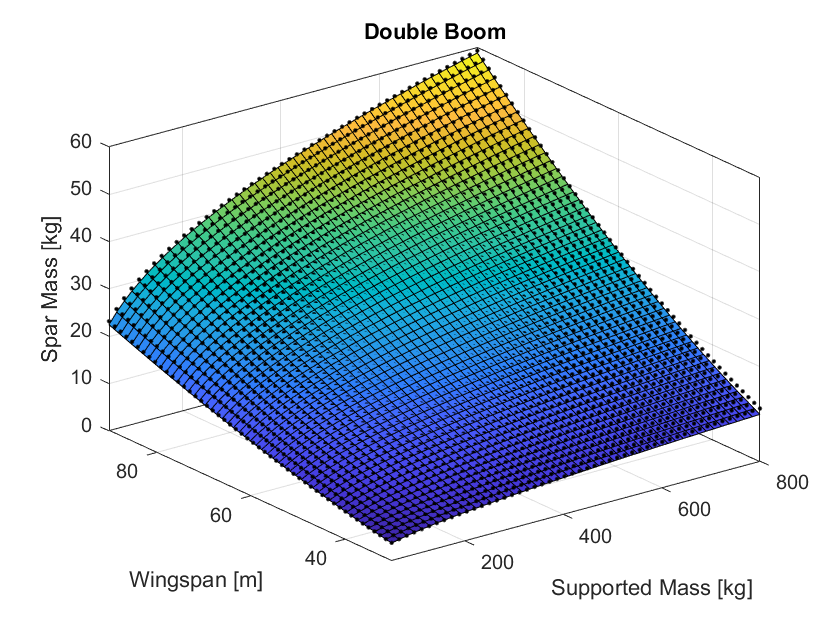

saveas(gcf,"plot_double_boom.png")

Triple Boom:

clear
load data_triple_boom.mat
fit = createFit(Masses,Spans,Spar_Masses*2 );
title("Triple Boom")
names = coeffnames(fit);
vals = coeffvalues(fit);
for i=1:length(names)
    disp(sprintf("%s = %.16f", names{i}, vals(i)))
end

c = 0.0059175282654185
m = 0.3807869156408368
n = 1.3862788430962647


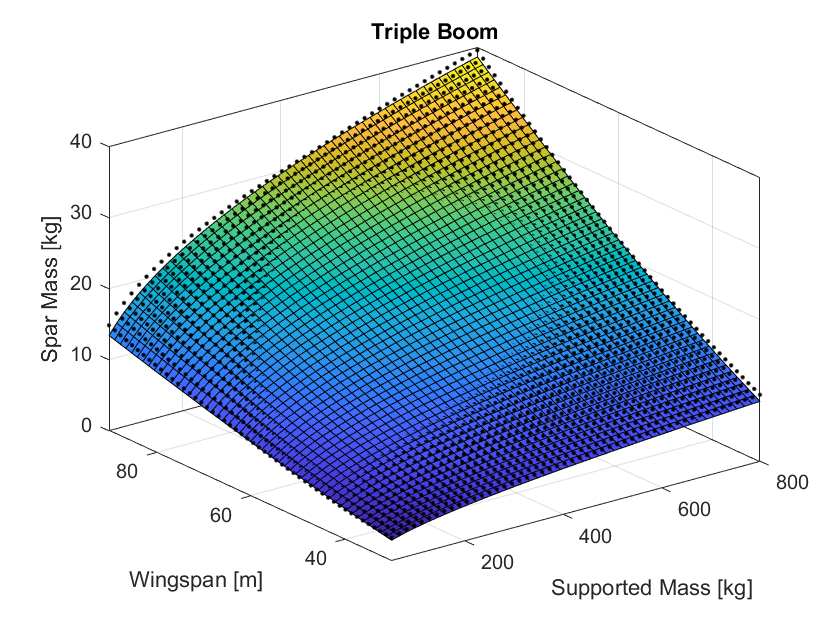

saveas(gcf,"plot_triple_boom.png")